clear all; close all; clc  %Declaraciones preeliminares
Ar1=['8'];                      %Nombre del Archivo
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';
time=49;                             %Hora
dx=20;                                %Grosor de la malla
puntosx=2001;                          %Tamaño horizontal de malla
puntosz=99;                           %Tamaño Vertical de malla
dis=(puntosx-1)*dx/2;                     %Limite horizontal
ejex1=((-dis):dx:(dis))/1000;              %En metros
clear dis
ejex2=ejex1;
ejex1(length(ejex1))=[];
% ejex2=(-dis:dx:dis)/1000;            %En metros 
gravedad=1.352;
timebar=1:1:time;
%  timebar=timebar.*10;
ftv=0;                           %Temperatura virtual 1 si, 0 no;
%Primero, cree niveles verticales geométricos a partir del geopotencial:
PHB1=ncread(Ar1,'PHB');
PHB=squeeze(PHB1);
clear PHB1
PH1=ncread(Ar1,'PH');
PH=squeeze(PH1);
clear PH1
gz=PHB+PH;
clear PHB1 PHB PH
gz2d=mean(gz,3,"omitmissing");
zi=400;     %Altura de la capa limite convectiva
% lim=1.25;      %Hasta donde se grafica
lim=2000;
ejez2=mean(gz2d)./(gravedad);
for i=1:1:puntosz
    ejez(i)=(ejez2(i)+ejez2(i+1))/2;
end
clear gz2d gz
%%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
    
%Leemos la variable a visualizar
un = squeeze(ncread(Ar1,Var1));
t = squeeze(ncread(Ar1,Var2))+100;
wn = squeeze(ncread(Ar1,Var3));
QV= squeeze(ncread(Ar1,'HFX'));
if ftv==1;
    t=t.*(1+0.61.*QV);
end
for i=1:1:puntosx-1   
    u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
end
for i=1:1:puntosz
    w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
end
wind=sqrt((u.^2)+(w.^2));
uprom = mean(u,1);                 %Promedio en X
uprom = repmat(uprom,puntosx-1,1);       %Creamos una matriz con el vector resultante
uprim = u-uprom;                  %Obtenemos la fluctuacion 
tprom = mean(t,1);
tprom = repmat(tprom,puntosx-1,1);
tprim = t-tprom;
wprom = mean(w,1);
wprom = repmat(wprom,puntosx-1,1);
wprim = w-wprom;
windprom=mean(wind,1);
windprom=repmat(windprom,puntosx-1,1);
windprim=wind-windprom;
SHF=squeeze(5940.*rms(wprim.*tprim,1));

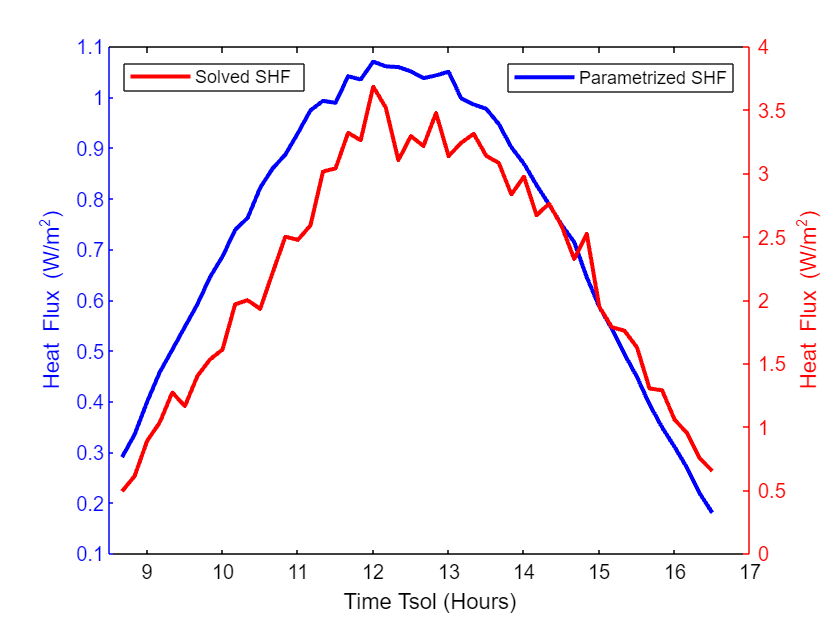

    SHF1=SHF(4,:);
    SHF2=SHF(8,:);
    HFX= squeeze(ncread(Ar1,'HFX'));
    HFX= squeeze(rms(HFX,1));

figure
tp = tiledlayout(1,1);
ay1 = axes(tp);
plot(ay1,timebar(2:1:time).*10/60-10/60+8.5,HFX(2:1:time)','b','LineWidth',2);
    ay1.XColor = 'black';
    ay1.YColor = 'b';
    ylabel('Heat Flux (W/m^{2})')
    xlabel('Time Tsol (Hours)')
    xlim([8.5 17]);
    % ylim([0.08 0.16])
    % ylim([-7 1.15]);
legend({'Parametrized SHF'},"AutoUpdate","on",'Location','northeast');
hold on
ay2 = axes(tp);
plot(ay2,timebar(2:1:time).*10/60-10/60+8.5,SHF2(2:1:time)','r','LineWidth',2)
    ay2.XAxisLocation = 'top';
    ay2.YAxisLocation = 'right';
    ay2.Color = 'none';
    ay2.XColor = 'black';
    ay2.YColor = 'r';
    ay1.Box = 'off';
    ay2.Box = 'off';
    % ylim([-25 50])
    xlim([8.5 17]);
    set(ay2, 'XTickLabel', {})
    legend({'Solved SHF'},"AutoUpdate","on",'Location','northwest');
hold off
    % xlim([9 12]);
    ylabel('Heat Flux (W/m^{2})')
print('Figura6A', '-dpng', '-r1000');